# Signal Modifier

Below code opens sample simulink model of this block

sig_mod_block_6

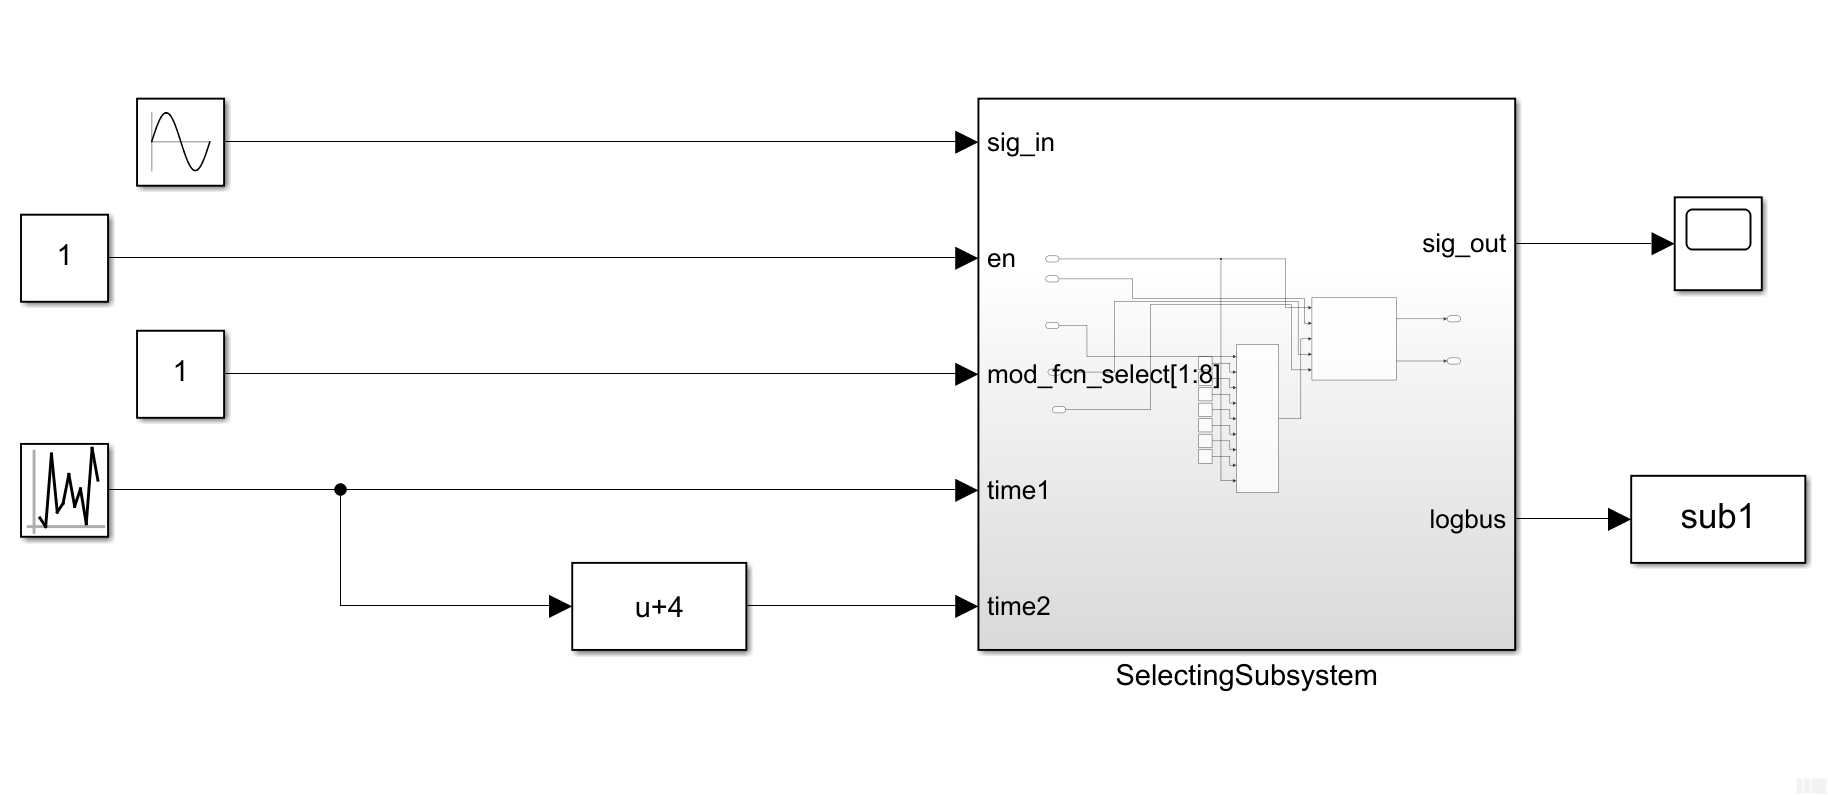

## How it works

The block replaces the input signal with the modification function between each time-interval pair *t1 t2*. In the above sample, the output signal is switched between values of the input signal and the first modification function preset (a step function, transitioning from 0 to 1 at 5 seconds).

Double click the scope block attached to *sig_out *to open the scope view. Then run the simulation to observe the signal modifier's effect on the input sine function.

sim('sig_mod_block_6');
open_system('sig_mod_block_6/Scope');

## sig_in and en inports

*sig_in* is the input signal to be modified. In this example case, a simple sine function. 

*en* is the enable. The block performs its signal modification when *en=1*. When *en=0* the block doesn't modify the input signal, making *sig_in=sig_out*

Double click on the constant block attached to the *en* inport to change the value.

set_param('sig_mod_block_6/Constant3','Value','1');

Double click the scope block attached to *sig_out *to open the scope view. Then run the simulation to observe the signal modifier's effect on the input sine function.

sim('sig_mod_block_6');
open_system('sig_mod_block_6/Scope');

### mod_fcn_select[1:8]

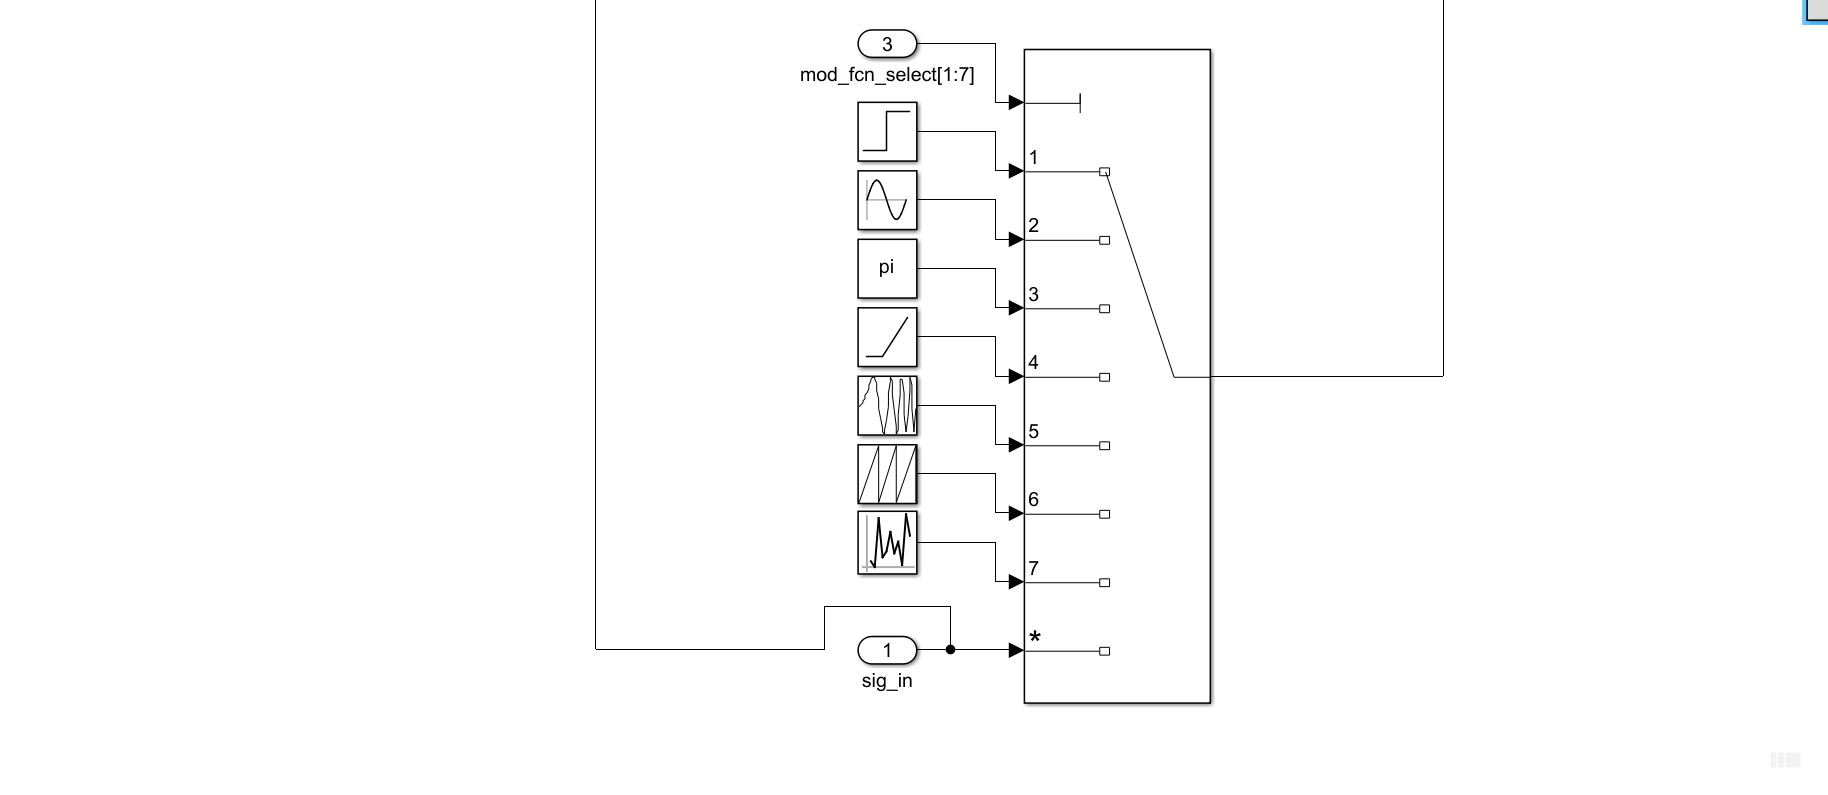

This is a view of inside the SelectingSubsystem (parent) block. The *mod_fcn_select[1:7] *input is used to select from preset modification functions (shown above). These are the functions that the input signal *sig_in* will be modified by. *mod_fcn_select[1:7] *can take on integer values from 1 to 7 to select one of the 7 preset modification functions. If *mod_fcn_select[1:7]* takes on another value, the default modification function will be selected (in this case *sig_in*, which effectively ensures no modification to the input signal). 

set_param('sig_mod_block_6/Constant1','Value','1');

Double click on the *SelectingSubsystem* parent block to access these presets.

open_system('sig_mod_block_6/SelectingSubsystem');

Double click on any of the preset modification functions to change their parameters.

open_system('sig_mod_block_6/SelectingSubsystem/Step');

Double click the scope block attached to *sig_out *to open the scope view. Then run the simulation to observe the signal modifier's effect on the input sine function.

sim('sig_mod_block_6');
open_system('sig_mod_block_6/Scope');